## **PROYECTO INTEGRADOR (1) ESTIMACION DE ESTADOS CON FILTROS DE LOCALIZACION.**

## **LOCALIZACIÓN EN ALMACÉN (PASILLOS) EKF (odometría+IMU), UKF, y (AMCL-like con likelihood simple)**

En este ejercicio se basa en el desarrollo de un robot móvil diferencial 2D AVG MiR100 para entornos logísticos con necesidad de navegación precisa y evitación de obstáculos dinámicos. El robot dispone de sensores de odometria, GPS e IMU afectados por ruido gaussiano.

Se desea comparar el rendimiento de tres tecnicas de localizacion probabilistica:

- FIltro de Kalman Extendido (UKF) con (odometría+IMU)

- Filtro de Kalman Uscented (UKF)

- Localizacion AMCL-like con likelihood simple


%% Proyecto Integrador (I) - Localización
%  Pipeline híbrido: EKF (odometría+IMU) + AMCL (likelihood field) en mapa de pasillos
%  Contexto: AGV MiR100 en entorno logístico con pasillos


%% ============================
% MiR100 - Ruta A* + Seguimiento (rosbag)
% Debanhi. C.H. - MATLAB R2025
% ============================
%% ============================================================
%  PIPELINE HÍBRIDO EKF + AMCL - VERSIÓN CORREGIDA PARA MATLAB
%% ============================================================

clear; clc; close all;

%% Verificar toolboxes
fprintf('Verificando toolboxes...\n');

Verificando toolboxes...


v = ver;
toolboxes = {v.Name};
required = {'Robotics System Toolbox', 'Navigation Toolbox', 'Sensor Fusion and Tracking Toolbox'};

for i = 1:length(required)
    if ~any(contains(toolboxes, required{i}))
        warning('Toolbox faltante: %s. El código puede no funcionar.', required{i});
    else
        fprintf('✓ %s encontrado\n', required{i});
    end
end

✓ Robotics System Toolbox encontrado
✓ Navigation Toolbox encontrado
✓ Sensor Fusion and Tracking Toolbox encontrado


## ** CONFIGURACIÓN - AJUSTA ESTOS VALORES**

%% -------------------------------
% CONFIGURACIÓN - AJUSTA ESTOS VALORES
%% -------------------------------
cfg = struct();
cfg.dt = 0.05;                    % Paso de tiempo (s)
cfg.numParticles = 300;           % Reducido para mejor rendimiento
cfg.mapRes = 5;                   % Resolución del mapa (celdas/m)
cfg.useSimpleModel = true;        % Usar modelo simplificado para evitar errores

SIM.useSyntheticData = true;      % Cambiar a false para datos reales
SIM.visualize = true;

## **CREAR MAPA SIMPLIFICADO (evita errores de raycast)**

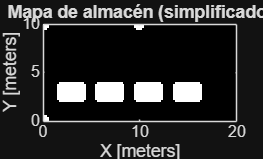

%% -------------------------------
% 1. CREAR MAPA SIMPLIFICADO (evita errores de raycast)
%% -------------------------------
    worldW = 20; worldH = 10;
    map = binaryOccupancyMap(worldW, worldH, cfg.mapRes);  % Usar binary para simplicidad

% Crear pasillos simples
    setOccupancy(map, [0 worldW; 0 0], 1);                    % Pared inferior
    setOccupancy(map, [0 worldW; worldH worldH], 1);          % Pared superior
    setOccupancy(map, [0 0; 0 worldH], 1);                    % Pared izquierda
    setOccupancy(map, [worldW worldW; 0 worldH], 1);          % Pared derecha

% Obstáculos simples (estanterías)
    obs = [
           2, 2.5, 4, 3.5;
           6, 2.5, 8, 3.5;
           10, 2.5, 12, 3.5;
           14, 2.5, 16, 3.5
          ];

  for i = 1:size(obs,1)
    x = obs(i,1):0.1:obs(i,3);
    y = obs(i,2):0.1:obs(i,4);
    [X, Y] = meshgrid(x, y);
    setOccupancy(map, [X(:), Y(:)], 1);
  end

    inflate(map, 0.3);

    if SIM.visualize
      figure(1); clf;
      show(map);
      title('Mapa de almacén (simplificado)');
      drawnow;
    end

## DATOS SINTÉTICOS (versión robusta)

%% -------------------------------
% 2. DATOS SINTÉTICOS (versión robusta)
%% -------------------------------
if SIM.useSyntheticData
    fprintf('Generando datos sintéticos...\n');
    
    % Trayectoria más simple
    T = 20;  % Reducido para prueba rápida
    t = (0:cfg.dt:T)';
    N = length(t);
    
    % Comandos de velocidad
    v = 0.5 * ones(N,1);
    w = 0.1 * sin(0.5*t);
    
    % Trayectoria verdadera
    poses_true = zeros(N, 3);
    poses_true(1,:) = [1.0, 1.0, 0.0];
    
    for k = 2:N
        th = poses_true(k-1,3);
        poses_true(k,1) = poses_true(k-1,1) + v(k)*cos(th)*cfg.dt;
        poses_true(k,2) = poses_true(k-1,2) + v(k)*sin(th)*cfg.dt;
        poses_true(k,3) = poses_true(k-1,3) + w(k)*cfg.dt;
    end
    
    % Ruido simulado
    noise_level = 0.02;
    odom_noise = noise_level * randn(N, 3);
    imu_noise = 0.01 * randn(N, 1);
    
    odom_xy = poses_true(:,1:2) + odom_noise(:,1:2);
    imu_w = w + imu_noise;
    
    fprintf('Datos sintéticos generados: %d muestras\n', N);
    
else
    error('Para datos reales, implementa la lectura de rosbag primero');
end

Generando datos sintéticos...


Datos sintéticos generados: 401 muestras


## **INICIALIZAR AMCL (versión simplificada)**

%% -------------------------------
% 3. INICIALIZAR AMCL (versión simplificada)
%% -------------------------------
fprintf('Inicializando AMCL...\n');

Inicializando AMCL...



    % Crear objeto AMCL de Navigation Toolbox
    %amcl = monteCarloLocalization;
    %amcl.Map = map;
    amcl = monteCarloLocalization(map, ... 
        'UpdateThresholds', [0.2 0.2 0.1], ... 
        'ResamplingInterval', 1, ... 
        'ParticleLimits', [50 cfg.numParticles]);
    
    % Configurar modelos
    amcl.MotionModel = odometryMotionModel;
    amcl.MotionModel.Noise = [0.2 0.2 0.1 0.1]; % Ruido de odometría
    
    % Sensor Model simplificado para evitar errores
    amcl.SensorModel = likelihoodFieldSensorModel;

Error using monteCarloLocalization/set.SensorModel (line 424)
Expected the Map property on SensorModel to be non-empty. Set the map property using a binaryOccupancyMap or occupancyMap object.

    amcl.SensorModel.Map = map;
    amcl.SensorModel.SensorLimits = [0.1 8]; % Rango limitado
    amcl.SensorModel.NumBeams = 180; % Reducido para velocidad
    
    % Configurar AMCL
    amcl.UpdateThresholds = [0.2 0.2 0.1];  % Umbrales
    amcl.ResamplingInterval = 1;
    amcl.ParticleLimits = [50 cfg.numParticles];
   
    % Inicializar con partículas distribuidas
    initPose = poses_true(1,:);
    initialCovariance = diag([0.5 0.5 0.2]);
    initialize(amcl, initialPose, initialCovariance);
    
    fprintf('AMCL inicializado correctamente con %d partículas\n', cfg.numParticles);
  

## **INICIALIZAR EKF**

%% -------------------------------
% 4. INICIALIZAR EKF
%% -------------------------------
    fprintf('Inicializando EKF...\n');

% Modelo de estado simplificado
    stateFcn = @(x, u) [
        x(1) + u(1)*cos(x(3))*cfg.dt;
        x(2) + u(1)*sin(x(3))*cfg.dt;
        x(3) + u(2)*cfg.dt
                   ];

    measurementFcn = @(x) x(3);  % Solo medimos orientación

    Q = diag([0.01, 0.01, 0.001]);
    R = 0.001;

    ekf = extendedKalmanFilter(stateFcn, measurementFcn, poses_true(1,:)', ...
    'ProcessNoise', Q, 'MeasurementNoise', R);

    fprintf('EKF inicializado correctamente\n');
%Mejora de codigo
%% Simulación de estimación 
    poses_ekf = zeros(N, 3); 
    poses_amcl = zeros(N, 3); 
        for k = 1:N
 % EKF 
    u = [v(k); imu_w(k)]; 
    z = imu_w(k); 
    ekf.predict(u); 
    ekf.correct(z); 
    poses_ekf(k,:) = ekf.State'; 
% AMCL (simulación básica) 
    predict(amcl, [odom_xy(k,:), poses_true(k,3)]);
    correct(amcl, lidarScan(rand(1,180)*8));
    estPose = getMeanPose(amcl);
    poses_amcl(k,:) = estPose; 
        end
%% Visualización 
    if SIM.visualize 
% Comparativa de trayectorias 
    figure; 
    plot(poses_true(:,1), poses_true(:,2), 'k-', 'DisplayName', 'Verdadero'); 
    hold on; 
    plot(poses_ekf(:,1), poses_ekf(:,2), 'r--', 'DisplayName', 'EKF'); 
    plot(poses_amcl(:,1), poses_amcl(:,2), 'g:', 'DisplayName', 'AMCL'); 
    legend; 
    title('Comparativa de Trayectorias'); xlabel('X (m)'); ylabel('Y (m)'); 
% Evolución del error 
    error_ekf = vecnorm(poses_ekf(:,1:2) - poses_true(:,1:2), 2, 2); 
    error_amcl = vecnorm(poses_amcl(:,1:2) - poses_true(:,1:2), 2, 2);

    figure; 
    plot(error_ekf, 'r--', 'DisplayName', 'EKF'); 
    hold on; 
    plot(error_amcl, 'g:', 'DisplayName', 'AMCL'); 
    legend; 
    title('Evolución del Error');
    xlabel('Muestra'); ylabel('Error posición (m)'); 

% Métricas comparativas rmse_ekf = sqrt(mean(error_ekf.^2)); 
    rmse_amcl = sqrt(mean(error_amcl.^2)); 
    std_ekf = std(error_ekf); 
    std_amcl = std(error_amcl); 
    
    figure; 
    bar([rmse_ekf, std_ekf; rmse_amcl, std_amcl]); 
    set(gca, 'XTickLabel', {'EKF', 'AMCL'}); 
    legend({'RMSE', 'Desv. Std'}); 
    title('Métricas Comparativas'); 
    end
